*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 1 : Simulate the Simplest 5G Network**

#    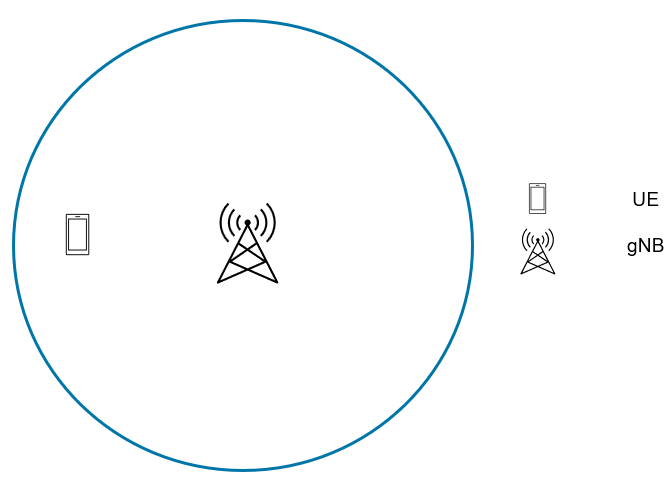

This exercise demonstrates a **basic 5G NR network simulation** using one gNB (base station) and 1 UE (user equipment). The goals are to:

- Understand how to create and configure gNB and UE nodes

- Set up the 5G network

- Simluate the network and capture statistics and explore visualization tools 

The following figure shows all the layers of NR node that can be modeled in MATLAB  

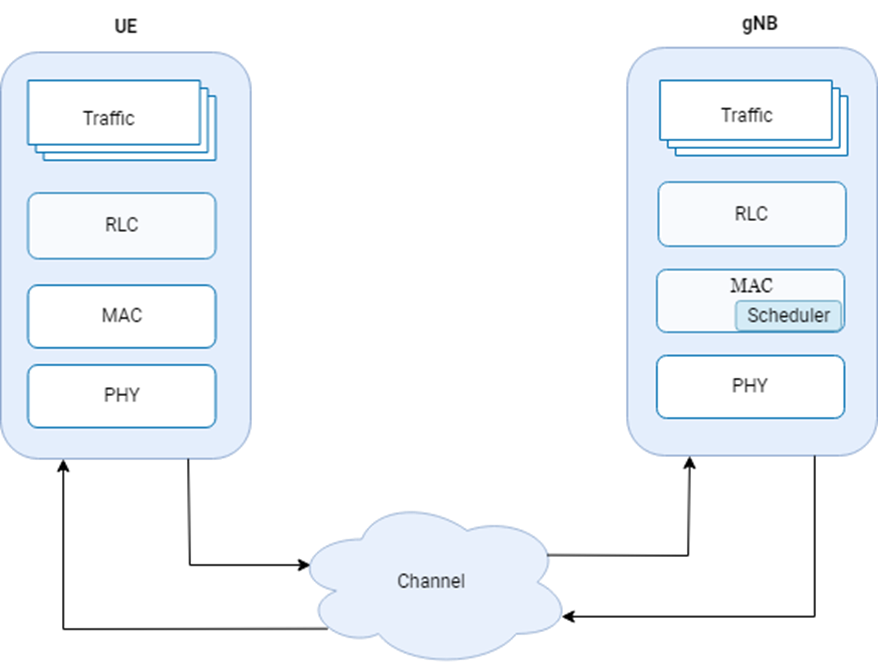

#### Close any previously opened figures and add the path to the helpers and utilities directories 

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
rng("default") % Reset the random number generator for reproducibility 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities

#### Initialize Variables and Wireless Network Simulator

wirelessnetworkSupportPackageCheck; % Wireless Network Simulation package is installed
networkSimulator = wirelessNetworkSimulator.init;% Initialize the Wireless Network Simulator
cellRadius = 500 ; % Radius of NR cell to be modeled in meters 
numFrameSimulation = 30; % Number of frames to simulate
simulationTime = numFrameSimulation*0.01 % Simulation Time in seconds 

simulationTime = 0.3000

gNBPosition = [0 0 30]; % [x y z] meters position in Cartesian coordinates

# Task #1/3 Create a NR base station 

% Use nrGNB() function to create a NR base station 
% Store NR base station in a variable named "gNB"
% Hint:Click the following link, and see the "Syntax" section.

[Help on creating 5G base station ](https://www.mathworks.com/help/5g/ref/nrgnb.html)

% Note : use the following values to start with
%    Position=gNBPosition
%    TransmitPower=34
%    SubcarrierSpacing=15000
%    CarrierFrequency=2.6e9
%    ChannelBandwidth=5e6
%    NumTransmitAntennas=1
%    NumReceiveAntennas=1
%    DuplexMode="FDD"
%    ReceiveGain=11
%    PHYAbstractionMethod="none"

% Write your code here
gNB = nrGNB( Name="gNB",...
    Position=gNBPosition, ...
    TransmitPower=33, ...
    SubcarrierSpacing=15000, ...
    CarrierFrequency=2.6e9, ...
    ChannelBandwidth=5e6, ...
    NumTransmitAntennas=1, ...
    NumReceiveAntennas=1, ...
    DuplexMode="FDD", ...
    ReceiveGain=11, ...
    PHYAbstractionMethod="none") 

gNB =   nrGNB with properties:

                        Name: "gNB"
                    Position: [0 0 30]

   Read-only properties:
                 NoiseFigure: 6
                 ReceiveGain: 11
               TransmitPower: 33
         NumTransmitAntennas: 1
          NumReceiveAntennas: 1
        PHYAbstractionMethod: "none"
                  DuplexMode: "FDD"
            CarrierFrequency: 2.6000e+09
            ChannelBandwidth: 5000000
           SubcarrierSpacing: 15000
           NumResourceBlocks: 25
                     NumHARQ: 16
    ULPowerControlParameters: [1×1 struct]
            SRSPeriodicityUE: 5
                          ID: 1

   Constant properties:
                    MCSTable: [28×4 table]


#### Configure Scheduler at NR base station (gNB)

configureScheduler(gNB,CSIMeasurementSignalDL="CSI-RS",Scheduler="RoundRobin");

# Task #2/3 Create a NR user equipment  

% Use nrUE() function to create a NR base station 
% Store NR base station in a variable named "UE"
% Hint:Click the following link, and see the "Syntax" section.

[Help on creating 5G user equipment ](https://www.mathworks.com/help/releases/R2025a/5g/ref/nrue.html)

% Create a UE (User Equipment) node
% Note : use the following values to start with
%    Name=ueName
%    Position=uePosition
%    ReceiveGain=0
%    NumTransmitAntennas=1
%    NumReceiveAntennas=1
%    PHYAbstractionMethod="none"

% Write your code here
ueName ="UE-1";       % UE Name 
uePosition = [200 100 1]; % UE position
UE = nrUE(Name=ueName, ...
    Position=uePosition, ...
    ReceiveGain=0, ...
    NumTransmitAntennas=1, ...
    NumReceiveAntennas=1, ...
    PHYAbstractionMethod="none")

UE =   nrUE with properties:

                    Name: "UE-1"
                Position: [200 100 1]

   Read-only properties:
             NoiseFigure: 6
             ReceiveGain: 0
           TransmitPower: 23
     NumTransmitAntennas: 1
      NumReceiveAntennas: 1
    PHYAbstractionMethod: "none"
         ConnectionState: "Idle"
                      ID: 2


#### Create an RLC layer

RLC bearers implement segmentation, reassembly, retransmission, reordering, and assists QoS

cfgRLCBearer = nrRLCBearerConfig(LogicalChannelID=5,RLCEntityType="UM",LogicalChannelGroup=2,Priority=16,PrioritizedBitRate=256,BucketSizeDuration=300)

cfgRLCBearer =   nrRLCBearerConfig with properties:

       LogicalChannelID: 5
          RLCEntityType: "UM"
             BufferSize: 400
          SNFieldLength: 12
        ReassemblyTimer: 30
    LogicalChannelGroup: 2
               Priority: 16
     PrioritizedBitRate: 256
     BucketSizeDuration: 300


# Task #3/3 Create the network   

% Use connectUE() function to connect gNB to corresponding UEs
% Hint:Click the following link, and see the "Syntax" section.
% Note : use the following values to start with
% gNB 
% UE  
% "RLCBearerConfig",cfgRLCBearer    

[Help on connecting UEs to gNB  ](https://www.mathworks.com/help/5g/ref/nrgnb.connectue.html)

% <enter code below>
connectUE(gNB, UE,"RLCBearerConfig",cfgRLCBearer);

#### **Install an application layer on gNB and UE **

appDataRate =  10e3; % Application data rate in kilobits per second (kbps)

Install an DL application traffic 

% Install the DL application traffic on gNB for the UE node
dlApp = networkTrafficOnOff(GeneratePacket=true,OnTime=numFrameSimulation*10e-3,OffTime=0,DataRate=appDataRate);
addTrafficSource(gNB,dlApp,DestinationNode=UE,LogicalChannelID=5);

Install an UL application traffic 

% Install the UL application traffic on the UE node for the gNB
ulApp = networkTrafficOnOff(GeneratePacket=true,OnTime=numFrameSimulation*10e-3,OffTime=0,DataRate=appDataRate);
addTrafficSource(UE,ulApp,LogicalChannelID=5)

#### **Add nodes to the network simulator **

% Add the gNB to the network simulator
addNodes(networkSimulator, gNB);
% Add UE to the network simulator
addNodes(networkSimulator, UE);

#### Add channel Model 

channelModel = "FSPL";
if strcmp(channelModel,"3GPP TR 38.901")
    % Define scenario boundaries
    pos = [reshape([gNB.Position],3,[])];
    minX = min(pos(1,:));          % x-coordinate of the left edge of the scenario in meters
    minY = min(pos(2,:));          % y-coordinate of the bottom edge of the scenario in meters
    width = max(pos(1,:)) - minX;  % Width (right edge of the 2D scenario) in meters, given as maxX - minX
    height = max(pos(2,:)) - minY; % Height (top edge of the 2D scenario) in meters, given as maxY - minY
    % Create the channel model
    channel = h38901Channel(Scenario="UMa",ScenarioExtents=[minX minY width height]);
    % Add the channel model to the simulator
    addChannelModel(networkSimulator,@channel.channelFunction);
    connectNodes(channel,networkSimulator,InterfererHasSmallScale=true);
end

#### Enable visualization, logging and IQ data capture

Visualize the network that you have created 

enableNetworkVisualization = true;
if enableNetworkVisualization
    networkVisualizer = helperNetworkVisualizer(SampleRate=100); % Sample rate indicates the visualization refresh rate in Hertz
    showBoundaries(networkVisualizer,gNBPosition,cellRadius,gNB.ID); % Show the cell boundary of each gNB
end

Visualize PHY and MAC performance   

PHYMetrics = true;
MACMetrics = true;
Direction  = false;
metricsVisualizer = helperNRMetricsVisualizer(gNB, ...
    UE, ...
    RefreshRate=100, ...
    PlotSchedulerMetrics=MACMetrics, ...
    PlotPhyMetrics=PHYMetrics, ...
    LinkDirection=Direction);

Set up the logger

enableTraces = true;
if enableTraces
    % Create an object to log scheduler traces
    simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation,gNB,UE);
    % Create an object to log for PHY traces
    simPhyLogger = helperNRPhyLogger(numFrameSimulation,gNB,UE);
    simulationLogFile = "simulationLogs"; % For logging the simulation traces
end

Capture IQ Samples

IQCapture = true;
if IQCapture
    iqSampleObj = helperCaptureIQSamples(gNB,Bandwidth=gNB.ChannelBandwidth);
end

#### Run the Simulation 

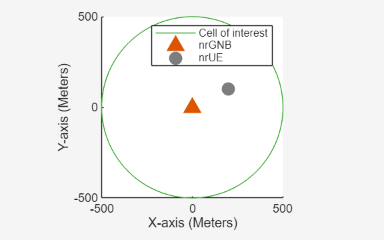

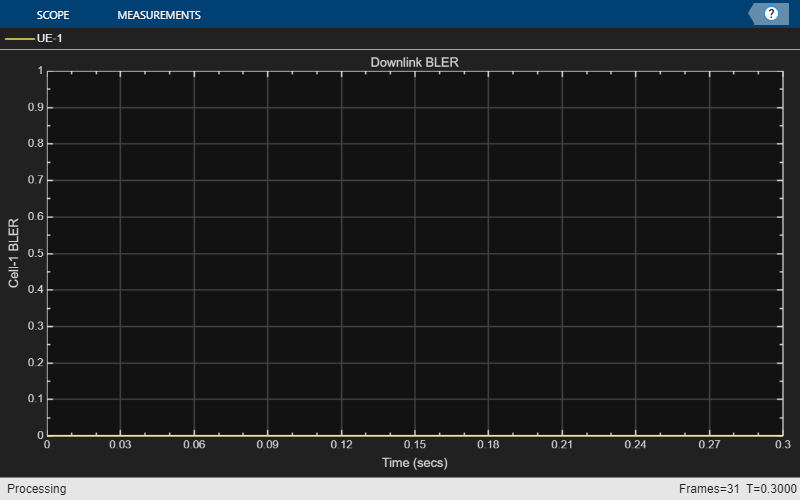

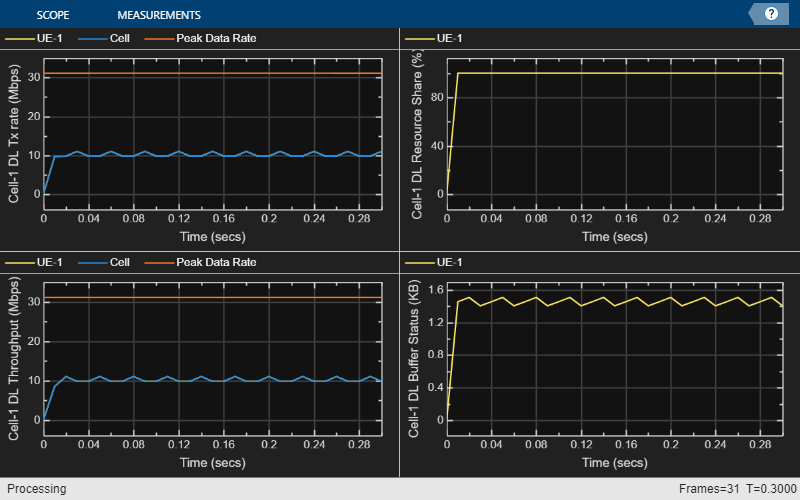

% Run the Simulation
run(networkSimulator, simulationTime);

### [Help on statistics](https://www.mathworks.com/help/5g/ref/nrgnb.statistics.html)

% Get statistics from the gNB
gnbStats = statistics(gNB, "all");
gnbStats.MAC.Retransmissions

ans = 0

#### gNB statistics 

gnbStats.App

ans = struct with fields:
    TransmittedPackets: 251
      TransmittedBytes: 376500
       ReceivedPackets: 247
         ReceivedBytes: 370500
          Destinations: [1×1 struct]


gnbStats.RLC

ans = struct with fields:
      TransmittedPackets: 452
        TransmittedBytes: 376358
    RetransmittedPackets: 0
      RetransmittedBytes: 0
         ReceivedPackets: 390
           ReceivedBytes: 371554
          DroppedPackets: 0
            DroppedBytes: 0
            Destinations: [1×1 struct]


gnbStats.MAC

ans = struct with fields:
     TransmittedPackets: 251
       TransmittedBytes: 384168
        ReceivedPackets: 143
          ReceivedBytes: 372706
        Retransmissions: 0
    RetransmissionBytes: 0
           Destinations: [1×1 struct]


gnbStats.PHY

ans = struct with fields:
    TransmittedPackets: 251
       ReceivedPackets: 143
        DecodeFailures: 0
          Destinations: [1×1 struct]


% Get statistics from both UEs (throughput, SINR, packet reception, etc.)
ueStats = statistics(UE);
ueStats.MAC.Retransmissions

ans = 0

#### UE statistics 

ueStats.PHY

ans = struct with fields:
    TransmittedPackets: 143
       ReceivedPackets: 250
        DecodeFailures: 0


ueStats.MAC

ans = struct with fields:
     TransmittedPackets: 143
       TransmittedBytes: 372706
        ReceivedPackets: 250
          ReceivedBytes: 382631
        Retransmissions: 0
    RetransmissionBytes: 0
       DLTransmissionRB: 3072
     DLRetransmissionRB: 0
       ULTransmissionRB: 2616
     ULRetransmissionRB: 0


ueStats.RLC

ans = struct with fields:
      TransmittedPackets: 390
        TransmittedBytes: 371554
    RetransmittedPackets: 0
      RetransmittedBytes: 0
         ReceivedPackets: 450
           ReceivedBytes: 374827
          DroppedPackets: 0
            DroppedBytes: 0


ueStats.App

ans = struct with fields:
    TransmittedPackets: 251
      TransmittedBytes: 376500
       ReceivedPackets: 249
         ReceivedBytes: 373500


At the end of the simulation, compare the achieved values for system performance indicators with theoretical peak values (considering zero overheads). Performance indicators displayed are:

- Achieved data rate (UL and DL)

- Achieved spectral efficiency (UL and DL)

- Block error rate (BLER) observed for UEs (UL and DL) 

The calculated peak values are in accordance with 3GPP TR 37.910.

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 31.11 Mbps. Achieved cell DL throughput: 10.20 Mbps
Achieved DL throughput for each UE: [10.2]
Peak DL spectral efficiency: 6.22 bits/s/Hz. Achieved DL spectral efficiency for cell: 2.04 bits/s/Hz
Block error rate for each UE in the DL direction: [0]



#### IQ sample visualization

enableIQVisualization  = true;
if enableIQVisualization && IQCapture
    signalAnalyzer(iqSampleObj.IQSamples.Data,SampleRate=7.68e6);
end

*Copyright 2025 The MathWorks, Inc.*


if enableTraces
    simulationLogs = cell(1,1);
    if gNB.DuplexMode == "FDD"
        logInfo = struct(DLTimeStepLogs=[],ULTimeStepLogs=[],...
            SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        [logInfo.DLTimeStepLogs,logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct(TimeStepLogs=[],SchedulingAssignmentLogs=[],PhyReceptionLogs=[]);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    % Obtain the scheduling assignments log
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger);
    % Obtain the Phy reception logs
    logInfo.PhyReceptionLogs = getReceptionLogs(simPhyLogger);
    % Save simulation logs in a MAT-file
    simulationLogs{1} = logInfo;
    save(simulationLogFile,"simulationLogs")
end
path(p);